## Lesli model


%{
L = [0, 8, 15; 1/3, 0, 0; 0, 1/2, 0];
x0 = [0, 1, 1];
[vals, vecs] = eig(L);
eig_vals = diag(vals)
lamb = max(eig_vals)

ind = vals == lamb;
vals(ind);

n = size(L);
n = n(1);
n = 1:n;

indxs = n(ind);
x_L = vecs(indxs,:)

t = 8;
x_t = (L^t) * x0'
x_t(1)
x_t(2)
x_t(3)

x = x0'
while (sum(x) <= 110)
    x1 = x;
    x = L * x;
end
x
x1

%}

## simple ode

%{

left = 0;
right = 45;
t1 = 40;

syms p(t);
ode1 = diff(p,t) == 0.0004 * p * (150 - p)
cond1 = p(0) == 20

P1 = dsolve(ode1,cond1)

figure;
hold on;
fplot(P1,[left, right]);

cond2 = p(0) == 300

P2 = dsolve(ode1,cond2)
fplot(P2,[left, right]);

y1 = double(subs(P1, 40))
y2 = double(subs(P2, 40))

%}

## Predator-prey (Lotka-Volterra), system 1

warning('off','all');
clc;
clear;
clear all;

top = 2; bot = -2; left = -2; right = 2;
sep=.5;

% х - густ попул жертви
% у - хижака

eps1 = 3;   % розмнож жерт без хиж
eps2 = 4;   % заг жерт без хиж
gam1 = 4;   % зменш жерт за наяв хиж
gam2 = 6;   % прир біомас хиж за наяв жерт

init1 = [0; 0] % перша точка рівноваги - вимирання

init1 =      0
     0


init2 = [eps2/gam2; eps1/gam1] % друга стаціонарна точка - коливання

init2 =     0.6667
    0.7500


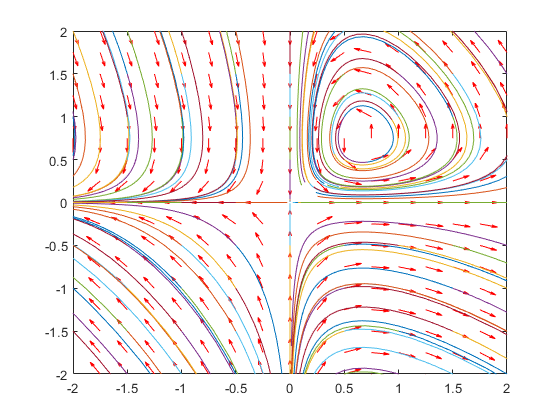


sys_no_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2); gam2*x(1)*x(2) - eps2*x(2)];

vectorfield(sys_no_interspec,left:.25:right,bot:.25:top);
hold on
for x0=left:sep:right
    for y0=bot:sep:top
        [ts,xs] = ode45(sys_no_interspec,[0 1],[x0 y0]);
        plot(xs(:,1),xs(:,2))
    end
end
for x0=left:sep:right
    for y0=bot:sep:top
        [ts,xs] = ode45(sys_no_interspec,[0 -1],[x0 y0]);
        plot(xs(:,1),xs(:,2))
    end
end
hold off
axis([left right bot top])
fsize=15;
%{
set(gca,’XTick’,-3:1:3,’FontSize’,fsize)
set(gca,’YTick’,-3:1:3,’FontSize’,fsize)
xlabel(’x(t)’,’FontSize’,fsize)
ylabel(’y(t)’,’FontSize’,fsize)
%}
hold off

## Predator-Prey, system 2 - with interspec

warning('off','all');

    clc;
    clear;
    clear all;

    top = 4; bot = -4; left = -4; right = 4;
    step=.5;
    time = .3;
    with_vectorfield = true;

    nodes = 40;
    x_field_step = (right - left)/nodes;
    y_field_step = (top - left)/nodes;

    % х - густ попул жертви
    % у - хижака

    eps1 = 3;   % розмнож жерт без хиж
    eps2 = 4;   % заг жерт без хиж
    gam1 = 4;   % зменш жерт за наяв хиж
    gam2 = 6;   % прир біомас хиж за наяв жерт
    
    % +
    beta1 = 1;  % внутр-вид взаєм жерт

    init1 = [0; 0] % перша точка рівноваги - вимирання

init1 =      0
     0


    init2 = [eps2/gam2; eps1/gam1] % друга стаціонарна точка - коливання

init2 =     0.6667
    0.7500


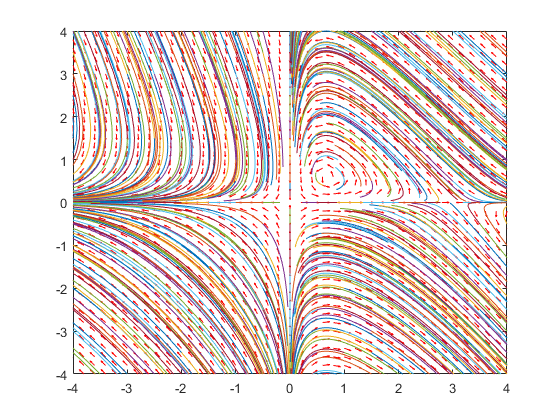


    sys_with_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2) - beta1*x(1)^2; gam2*x(1)*x(2) - eps2*x(2)];

    if with_vectorfield
        vectorfield(sys_with_interspec,left:x_field_step:right,bot:y_field_step:top);
    end
    hold on


    for x0=left:step:right
        for y0=bot:step:top
            [ts,xs] = ode45(sys_with_interspec,[0 time],[x0 y0]);
            plot(xs(:,1),xs(:,2))
        end
    end
    for x0=left:step:right
        for y0=bot:step:top
            [ts,xs] = ode45(sys_with_interspec,[0 -time],[x0 y0]);
            plot(xs(:,1),xs(:,2))
        end
    end
    hold off
    axis([left right bot top])
    fsize=15;
    %{
    set(gca,’XTick’,-3:1:3,’FontSize’,fsize)
    set(gca,’YTick’,-3:1:3,’FontSize’,fsize)
    xlabel(’x(t)’,’FontSize’,fsize)
    ylabel(’y(t)’,’FontSize’,fsize)
    %}
    hold off

## Separate plots

phase_port1_1();
phase_port1_2();
phase_port2_1();
phase_port2_2();
phase_port2_3();

## Predator-Prey. some solutions

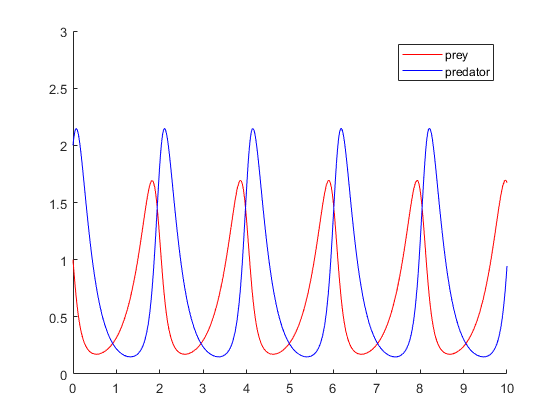

clc;
clear;
clear all;

x10 = 1; y10 = 2;
x20 = 2; y20 = 1;

init1 = [x10 y10];
init2 = [x20 y20];

time = 10;

eps1 = 3;   % розмнож жерт без хиж
eps2 = 4;   % заг жерт без хиж
gam1 = 4;   % зменш жерт за наяв хиж
gam2 = 6;   % прир біомас хиж за наяв жерт

% +
beta1 = 1;  % внутр-вид взаєм жерт


%% syst1, x0 > y0
sys_no_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2); gam2*x(1)*x(2) - eps2*x(2)];

figure;
hold on;
options = odeset('RelTol',1e-4,'AbsTol',1e-4);
[t,xa] = ode45(sys_no_interspec, [0 time], init1, options);
plot(t,xa(:,1), 'r');
plot(t,xa(:,2), 'b');
legend('prey','predator');
axis([0 time 0 3]);
hold off;

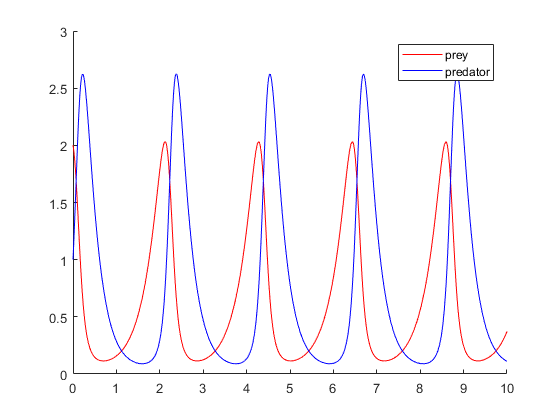


%% syst1, x0 < y0
% sys_no_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2); gam2*x(1)*x(2) - eps2*x(2)];

figure;
hold on;
options = odeset('RelTol',1e-4,'AbsTol',1e-4);
[t,xa] = ode45(sys_no_interspec, [0 time], init2, options);
plot(t,xa(:,1), 'r');
plot(t,xa(:,2), 'b');
legend('prey','predator');
axis([0 time 0 3]);
hold off;



%% syst2, x0 > y0
sys_with_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2) - beta1*x(1)^2; gam2*x(1)*x(2) - eps2*x(2)];

figure;
hold on;
options = odeset('RelTol',1e-4,'AbsTol',1e-4);
[t,xa] = ode45(sys_no_interspec, [0 time], init1, options);
plot(t,xa(:,1), 'r');
plot(t,xa(:,2), 'b');
legend('prey','predator');
axis([0 time 0 3]);
hold off;

x =    -0.1000   -0.3400         0         0         0         0


y =    -0.1000    0.4600         0         0         0         0


x =    -0.1000   -0.3400   -0.3944         0         0         0


y =    -0.1000    0.4600   -2.7784         0         0         0


x =    -0.1000   -0.3400   -0.3944   -5.5664         0         0


y =    -0.1000    0.4600   -2.7784   17.6884         0         0


x =    -0.1000   -0.3400   -0.3944   -5.5664  377.1440         0


y =    -0.1000    0.4600   -2.7784   17.6884 -661.5185         0


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0038    9.9908


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0007   -1.4943


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0038    9.9908


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0007   -1.4943


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0038    9.9908


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0007   -1.4943


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0038    9.9908


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0007   -1.4943


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0023    9.9908


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0004   -1.4943


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0023    3.7504


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0041   -5.5989


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0023    3.7504


y =    1.0e+05 *

         0         0   -0.0000    0.0001   -0.0041   -5.5989


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0023    3.7504


y =    1.0e+05 *

         0         0         0    0.0001   -0.0041   -5.5989


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0000    0.0023    3.7504


y =    1.0e+05 *

         0         0         0         0   -0.0041   -5.5989


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    3.7504


y =    1.0e+05 *

         0         0         0         0         0   -5.5989


x =    -0.1000   -0.3000   -0.9000   -2.7000   -8.1000  -24.3000


y =      0     0     0     0     0     0


x =    -0.1000   -0.2800   -0.9000   -2.7000   -8.1000  -24.3000


y =     0.0500   -0.2300         0         0         0         0


x =    -0.1000   -0.2800   -1.0976   -2.7000   -8.1000  -24.3000


y =     0.0500   -0.2300    1.3064         0         0         0


x =    -0.1000   -0.2800   -1.0976    2.4428   -8.1000  -24.3000


y =     0.0500   -0.2300    1.3064  -13.8290         0         0


x =    -0.1000   -0.2800   -1.0976    2.4428  142.4557  -24.3000


y =     0.0500   -0.2300    1.3064  -13.8290 -147.3747         0


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0001    0.0002    0.0142    8.4405


y =    1.0e+05 *

    0.0000   -0.0000    0.0000   -0.0001   -0.0015   -1.2538


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0001    0.0002    0.0142    8.4405


y =    1.0e+05 *

    0.0000   -0.0000    0.0000   -0.0001   -0.0015   -1.2538


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0001    0.0002    0.0142    8.4405


y =    1.0e+05 *

    0.0000   -0.0000    0.0000   -0.0001   -0.0015   -1.2538


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0001    0.0009    0.0142    8.4405


y =    1.0e+05 *

    0.0000   -0.0000    0.0000   -0.0003   -0.0015   -1.2538


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0001    0.0009    0.1102    8.4405


y =    1.0e+05 *

    0.0000   -0.0000    0.0000   -0.0003   -0.0149   -1.2538


x =    1.0e+06 *

   -0.0000   -0.0000   -0.0000    0.0000    0.0011    6.5940


y =    1.0e+06 *

    0.0000   -0.0000    0.0000   -0.0000   -0.0015   -9.8801


x =    1.0e+06 *

   -0.0000   -0.0000   -0.0000    0.0000    0.0011    6.5940


y =    1.0e+06 *

   -0.0000    0.0000    0.0000   -0.0000   -0.0015   -9.8801


x =    1.0e+06 *

   -0.0000   -0.0000   -0.0000    0.0000    0.0011    6.5940


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000   -0.0000   -0.0015   -9.8801


x =    1.0e+06 *

   -0.0000   -0.0000   -0.0000   -0.0000    0.0011    6.5940


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0015   -9.8801


x =    1.0e+06 *

   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    6.5940


y =    1.0e+06 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0002   -9.8801


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0003    0.0108    9.5603


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0022   -1.4204


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0003    0.0108    9.5603


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0022   -1.4204


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0003    0.0108    9.5603


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0022   -1.4204


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0002    0.0108    9.5603


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0022   -1.4204


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0002    0.0057    9.5603


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0012   -1.4204


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0002    0.0057    2.7926


y =    1.0e+04 *

   -0.0000    0.0000   -0.0001    0.0006   -0.0122   -4.1144


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0002    0.0057    2.7926


y =    1.0e+04 *

         0         0   -0.0001    0.0006   -0.0122   -4.1144


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0002    0.0057    2.7926


y =    1.0e+04 *

         0         0         0    0.0006   -0.0122   -4.1144


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0001    0.0057    2.7926


y =    1.0e+04 *

         0         0         0         0   -0.0122   -4.1144


x =    1.0e+04 *

   -0.0000   -0.0000   -0.0000   -0.0001   -0.0004    2.7926


y =    1.0e+04 *

         0         0         0         0         0   -4.1144


x =    -0.0500   -0.1500   -0.4500   -1.3500   -4.0500  -12.1500


y =      0     0     0     0     0     0


x =    -0.0500   -0.1400   -0.4500   -1.3500   -4.0500  -12.1500


y =     0.0500   -0.2150         0         0         0         0


x =    -0.0500   -0.1400   -0.5404   -1.3500   -4.0500  -12.1500


y =     0.0500   -0.2150    1.0406         0         0         0


x =    -0.0500   -0.1400   -0.5404    0.6282   -4.0500  -12.1500


y =     0.0500   -0.2150    1.0406   -7.5364         0         0


x =    -0.0500   -0.1400   -0.5404    0.6282   20.8209  -12.1500


y =     0.0500   -0.2150    1.0406   -7.5364    1.7412         0


x =    -0.0500   -0.1400   -0.5404    0.6282   20.8209  -82.5486


y =     0.0500   -0.2150    1.0406   -7.5364    1.7412  210.5522


x =    -0.0500   -0.1300   -0.5404    0.6282   20.8209  -82.5486


y =     0.1000   -0.4300    1.0406   -7.5364    1.7412  210.5522


x =    -0.0500   -0.1300   -0.6136    0.6282   20.8209  -82.5486


y =     0.1000   -0.4300    2.0554   -7.5364    1.7412  210.5522


x =    -0.0500   -0.1300   -0.6136    3.2040   20.8209  -82.5486


y =     0.1000   -0.4300    2.0554  -15.7888    1.7412  210.5522


x =    -0.0500   -0.1300   -0.6136    3.2040  211.9590  -82.5486


y =     0.1000   -0.4300    2.0554  -15.7888 -240.3656  210.5522


x =    1.0e+05 *

   -0.0000   -0.0000   -0.0000    0.0000    0.0021    2.0443


y =    1.0e+05 *

    0.0000   -0.0000    0.0000   -0.0002   -0.0024   -3.0472


x =    1.0e+05 *

         0         0   -0.0000    0.0000    0.0021    2.0443


y =    1.0e+05 *

   -0.0000    0.0000    0.0000   -0.0002   -0.0024   -3.0472


x =    1.0e+05 *

         0         0         0    0.0000    0.0021    2.0443


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000   -0.0002   -0.0024   -3.0472


x =    1.0e+05 *

         0         0         0         0    0.0021    2.0443


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0024   -3.0472


x =    1.0e+05 *

         0         0         0         0         0    2.0443


y =    1.0e+05 *

   -0.0000    0.0000   -0.0000    0.0001   -0.0003   -3.0472


x =      0     0     0     0     0     0


y =    -0.1000    0.4000   -1.6000    6.4000  -25.6000  102.4000


x =      0     0     0     0     0     0


y =    -0.0500    0.2000   -1.6000    6.4000  -25.6000  102.4000


x =      0     0     0     0     0     0


y =    -0.0500    0.2000   -0.8000    6.4000  -25.6000  102.4000


x =      0     0     0     0     0     0


y =    -0.0500    0.2000   -0.8000    3.2000  -25.6000  102.4000


x =      0     0     0     0     0     0


y =    -0.0500    0.2000   -0.8000    3.2000  -12.8000  102.4000


x =      0     0     0     0     0     0


y =    -0.0500    0.2000   -0.8000    3.2000  -12.8000   51.2000


x =      0     0     0     0     0     0


y =          0         0   -0.8000    3.2000  -12.8000   51.2000


x =      0     0     0     0     0     0


y =          0         0         0    3.2000  -12.8000   51.2000


x =      0     0     0     0     0     0


y =          0         0         0         0  -12.8000   51.2000


x =      0     0     0     0     0     0


y =          0         0         0         0         0   51.2000


x =      0     0     0     0     0     0


y =      0     0     0     0     0     0


x =      0     0     0     0     0     0


y =     0.0500   -0.2000         0         0         0         0


x =      0     0     0     0     0     0


y =     0.0500   -0.2000    0.8000         0         0         0


x =      0     0     0     0     0     0


y =     0.0500   -0.2000    0.8000   -3.2000         0         0


x =      0     0     0     0     0     0


y =     0.0500   -0.2000    0.8000   -3.2000   12.8000         0


x =      0     0     0     0     0     0


y =     0.0500   -0.2000    0.8000   -3.2000   12.8000  -51.2000


x =      0     0     0     0     0     0


y =     0.1000   -0.4000    0.8000   -3.2000   12.8000  -51.2000


x =      0     0     0     0     0     0


y =     0.1000   -0.4000    1.6000   -3.2000   12.8000  -51.2000


x =      0     0     0     0     0     0


y =     0.1000   -0.4000    1.6000   -6.4000   12.8000  -51.2000


x =      0     0     0     0     0     0


y =     0.1000   -0.4000    1.6000   -6.4000   25.6000  -51.2000


x =      0     0     0     0     0     0


y =     0.1000   -0.4000    1.6000   -6.4000   25.6000 -102.4000


x =     0.0500    0.1700         0         0         0         0


y =    -0.1000    0.3700    1.6000   -6.4000   25.6000 -102.4000


x =     0.0500    0.1700    0.2584         0         0         0


y =    -0.1000    0.3700   -1.1026   -6.4000   25.6000 -102.4000


x =     0.0500    0.1700    0.2584    1.9148         0         0


y =    -0.1000    0.3700   -1.1026    2.7009   25.6000 -102.4000


x =     0.0500    0.1700    0.2584    1.9148  -14.9429         0


y =    -0.1000    0.3700   -1.1026    2.7009   20.2275 -102.4000


x =    1.0e+03 *

    0.0001    0.0002    0.0003    0.0019   -0.0149    1.1642


y =    1.0e+03 *

   -0.0001    0.0004   -0.0011    0.0027    0.0202   -1.8945


x =    1.0e+03 *

    0.0001    0.0002    0.0003    0.0019   -0.0149    1.1642


y =    1.0e+03 *

   -0.0001    0.0002   -0.0011    0.0027    0.0202   -1.8945


x =    1.0e+03 *

    0.0001    0.0002    0.0004    0.0019   -0.0149    1.1642


y =    1.0e+03 *

   -0.0001    0.0002   -0.0006    0.0027    0.0202   -1.8945


x =    1.0e+03 *

    0.0001    0.0002    0.0004    0.0019   -0.0149    1.1642


y =    1.0e+03 *

   -0.0001    0.0002   -0.0006    0.0010    0.0202   -1.8945


x =    1.0e+03 *

    0.0001    0.0002    0.0004    0.0019   -0.0021    1.1642


y =    1.0e+03 *

   -0.0001    0.0002   -0.0006    0.0010    0.0076   -1.8945


x =     0.0500    0.1600    0.3616    1.8983   -2.1216   58.1910


y =    -0.0500    0.1850   -0.5624    1.0294    7.6069 -127.2614


x =     0.0500    0.1500    0.3616    1.8983   -2.1216   58.1910


y =          0         0   -0.5624    1.0294    7.6069 -127.2614


x =     0.0500    0.1500    0.4500    1.8983   -2.1216   58.1910


y =          0         0         0    1.0294    7.6069 -127.2614


x =     0.0500    0.1500    0.4500    1.3500   -2.1216   58.1910


y =          0         0         0         0    7.6069 -127.2614


x =     0.0500    0.1500    0.4500    1.3500    4.0500   58.1910


y =          0         0         0         0         0 -127.2614


x =     0.0500    0.1500    0.4500    1.3500    4.0500   12.1500


y =      0     0     0     0     0     0


x =     0.0500    0.1400    0.4500    1.3500    4.0500   12.1500


y =     0.0500   -0.1850         0         0         0         0


x =     0.0500    0.1400    0.5236    1.3500    4.0500   12.1500


y =     0.0500   -0.1850    0.5846         0         0         0


x =     0.0500    0.1400    0.5236    0.3464    4.0500   12.1500


y =     0.0500   -0.1850    0.5846   -0.5018         0         0


x =     0.0500    0.1400    0.5236    0.3464    1.7346   12.1500


y =     0.0500   -0.1850    0.5846   -0.5018    0.9643         0


x =     0.0500    0.1400    0.5236    0.3464    1.7346   -1.4866


y =     0.0500   -0.1850    0.5846   -0.5018    0.9643    6.1785


x =     0.0500    0.1300    0.5236    0.3464    1.7346   -1.4866


y =     0.1000   -0.3700    0.5846   -0.5018    0.9643    6.1785


x =     0.0500    0.1300    0.5824    0.3464    1.7346   -1.4866


y =     0.1000   -0.3700    1.1914   -0.5018    0.9643    6.1785


x =     0.0500    0.1300    0.5824   -1.0283    1.7346   -1.4866


y =     0.1000   -0.3700    1.1914   -0.6024    0.9643    6.1785


x =     0.0500    0.1300    0.5824   -1.0283   -5.5625   -1.4866


y =     0.1000   -0.3700    1.1914   -0.6024    6.1259    6.1785


x =     0.0500    0.1300    0.5824   -1.0283   -5.5625  119.6148


y =     0.1000   -0.3700    1.1914   -0.6024    6.1259 -228.9572


x =     0.1000    0.3400    0.5824   -1.0283   -5.5625  119.6148


y =    -0.1000    0.3400    1.1914   -0.6024    6.1259 -228.9572


x =     0.1000    0.3400    0.5576   -1.0283   -5.5625  119.6148


y =    -0.1000    0.3400   -0.6664   -0.6024    6.1259 -228.9572


x =     0.1000    0.3400    0.5576    3.1591   -5.5625  119.6148


y =    -0.1000    0.3400   -0.6664    0.4361    6.1259 -228.9572


x =     0.1000    0.3400    0.5576    3.1591    3.9667  119.6148


y =    -0.1000    0.3400   -0.6664    0.4361    6.5217 -228.9572


x =     0.1000    0.3400    0.5576    3.1591    3.9667  -91.5785


y =    -0.1000    0.3400   -0.6664    0.4361    6.5217  129.1312


x =     0.1000    0.3200    0.5576    3.1591    3.9667  -91.5785


y =    -0.0500    0.1700   -0.6664    0.4361    6.5217  129.1312


x =     0.1000    0.3200    0.7424    3.1591    3.9667  -91.5785


y =    -0.0500    0.1700   -0.3536    0.4361    6.5217  129.1312


x =     0.1000    0.3200    0.7424    3.2773    3.9667  -91.5785


y =    -0.0500    0.1700   -0.3536   -0.1607    6.5217  129.1312


x =     0.1000    0.3200    0.7424    3.2773   11.9381  -91.5785


y =    -0.0500    0.1700   -0.3536   -0.1607   -2.5167  129.1312


x =     0.1000    0.3200    0.7424    3.2773   11.9381  155.9944


y =    -0.0500    0.1700   -0.3536   -0.1607   -2.5167 -170.2033


x =     0.1000    0.3000    0.7424    3.2773   11.9381  155.9944


y =          0         0   -0.3536   -0.1607   -2.5167 -170.2033


x =     0.1000    0.3000    0.9000    3.2773   11.9381  155.9944


y =          0         0         0   -0.1607   -2.5167 -170.2033


x =     0.1000    0.3000    0.9000    2.7000   11.9381  155.9944


y =          0         0         0         0   -2.5167 -170.2033


x =     0.1000    0.3000    0.9000    2.7000    8.1000  155.9944


y =          0         0         0         0         0 -170.2033


x =     0.1000    0.3000    0.9000    2.7000    8.1000   24.3000


y =      0     0     0     0     0     0


x =     0.1000    0.2800    0.9000    2.7000    8.1000   24.3000


y =     0.0500   -0.1700         0         0         0         0


x =     0.1000    0.2800    1.0304    2.7000    8.1000   24.3000


y =     0.0500   -0.1700    0.3944         0         0         0


x =     0.1000    0.2800    1.0304    1.4656    8.1000   24.3000


y =     0.0500   -0.1700    0.3944    0.8607         0         0


x =     0.1000    0.2800    1.0304    1.4656   -0.6492   24.3000


y =     0.0500   -0.1700    0.3944    0.8607    4.1262         0


x =     0.1000    0.2800    1.0304    1.4656   -0.6492    8.7676


y =     0.0500   -0.1700    0.3944    0.8607    4.1262  -32.5778


x =     0.1000    0.2600    1.0304    1.4656   -0.6492    8.7676


y =     0.1000   -0.3400    0.3944    0.8607    4.1262  -32.5778


x =     0.1000    0.2600    1.1336    1.4656   -0.6492    8.7676


y =     0.1000   -0.3400    0.8296    0.8607    4.1262  -32.5778


x =     0.1000    0.2600    1.1336   -0.3609   -0.6492    8.7676


y =     0.1000   -0.3400    0.8296    2.3242    4.1262  -32.5778


x =     0.1000    0.2600    1.1336   -0.3609    2.2728    8.7676


y =     0.1000   -0.3400    0.8296    2.3242  -14.3302  -32.5778


x =     0.1000    0.2600    1.1336   -0.3609    2.2728  137.0951


y =     0.1000   -0.3400    0.8296    2.3242  -14.3302 -138.0944


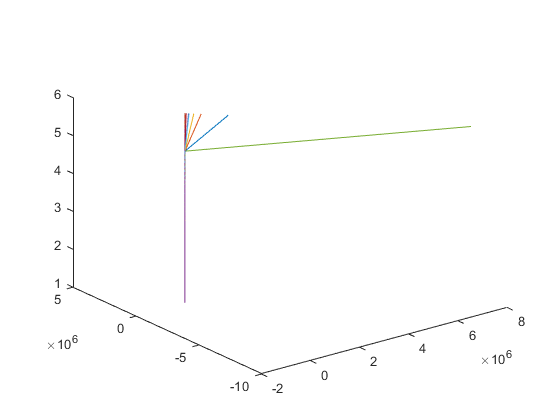


%% syst2, x0 < y0
% sys_with_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2) - beta1*x(1)^2; gam2*x(1)*x(2) - eps2*x(2)];

figure;
hold on;
options = odeset('RelTol',1e-4,'AbsTol',1e-4);
[t,xa] = ode45(sys_no_interspec, [0 time], init2, options);
plot(t,xa(:,1), 'r');
plot(t,xa(:,2), 'b');
legend('prey','predator');
axis([0 time 0 3]);
hold off;

## Predator-Prey. 3D plot. Attempt 2

warning('off','all');
clc;
clear;
clear all;

top = 4; bot = -4; left = -4; right = 4;
sep=.5;
time = 1;

% time_step = 0.01;
% t = -time:time_step:time;

% х - густ попул жертви
% у - хижака

eps1 = 3;   % розмнож жерт без хиж
eps2 = 4;   % заг жерт без хиж
gam1 = 4;   % зменш жерт за наяв хиж
gam2 = 6;   % прир біомас хиж за наяв жерт

init1 = [0; 0] % перша точка рівноваги - вимирання

init1 =      0
     0


init2 = [eps2/gam2; eps1/gam1] % друга стаціонарна точка - коливання

init2 =     0.6667
    0.7500


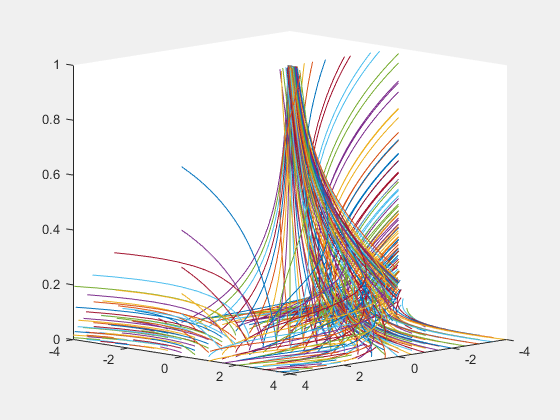


sys_no_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2); gam2*x(1)*x(2) - eps2*x(2)];

%%{
figure;
view([right, top, time]);
set(gcf,'Visible','on');
hold on
for x0=left:sep:right
    for y0=bot:sep:top
        [ts,xs] = ode45(sys_no_interspec,[0 time],[x0 y0]);
        plot3(xs(:,1),xs(:,2),ts(:,1))
        hold on;
    end
end
axis([left, right, bot, top, 0, time])

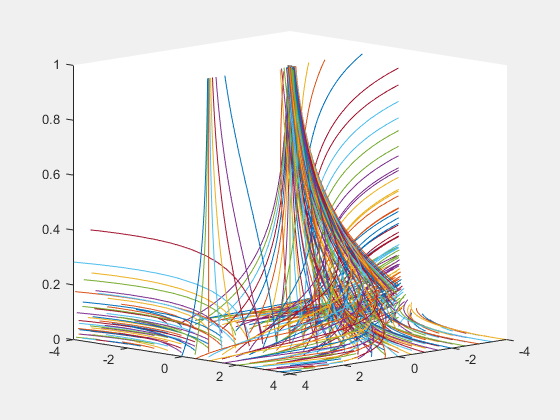

warning('off','all');
clc;
clear;
clear all;

top = 4; bot = -4; left = -4; right = 4;
sep=.5;
time = 1;

% time_step = 0.01;
% t = -time:time_step:time;

% х - густ попул жертви
% у - хижака

eps1 = 3;   % розмнож жерт без хиж
eps2 = 4;   % заг жерт без хиж
gam1 = 4;   % зменш жерт за наяв хиж
gam2 = 6;   % прир біомас хиж за наяв жерт
beta1 = 1;

sys_with_interspec = @(t,x) [eps1*x(1) - gam1*x(1)*x(2) - beta1*x(1)^2; gam2*x(1)*x(2) - eps2*x(2)];

%%{
figure;
view([right, top, time]);
set(gcf,'Visible','on');
hold on
for x0=left:sep:right
    for y0=bot:sep:top
        [ts,xs] = ode45(sys_with_interspec,[0 time],[x0 y0]);
        plot3(xs(:,1),xs(:,2),ts(:,1))
        hold on;
    end
end
axis([left, right, bot, top, 0, time])

%{
a = 1:.5:5
x = 0;
for i = a
    x = x + 1
end
%}

%{
n = 10;
t = 1:n;
ndims(t)
xt = sin(t);
yt = cos(t);
figure;
hold on;
plot3(xt,yt,t);
angle();
axis([-1, 1, -1, 1, 0, n]);
%}